clc; clear variables;

# 2 Zeit diskrete Signale

## 2.2 Faltung

x = [5 4 3 2 1];
u = [1 1 1];

y = faltung(x,u);

%Probe
%falt = conv(x,u)

## 2.3 Formatierung von Graphen

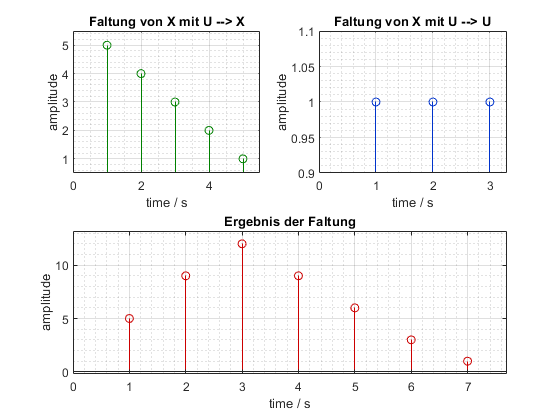

figure (1); 
subplot(2,2,1)
stem(x,'Color',[0 0.5 0])
stem_properties('Faltung von X mit U --> X','time / s','amplitude',x);

subplot(2,2,2)
stem(u,'Color',[0 0.2 0.8])
stem_properties('Faltung von X mit U --> U','time / s','amplitude',u);

subplot(2,2,[3,4])
stem(y,'Color',[0.8 0 0])
stem_properties('Ergebnis der Faltung','time / s','amplitude',y);

## 2.4 Systemeigenschaften

nSymbols = 2^3;
%Erzeugung von 2 zufälligen Signalen

rng(1)
data1 = randn(1, nSymbols);                 
rng(13)                         % gleicher Seed bedeutet gleiche Zufallszahlenfolge
data2 = randn(1, nSymbols);

%Dirac zur späteren Kausalitätsprüfung
dirac_1_pos = floor(length(data1)/2);
dirac = zeros(1, length(data1));
dirac(dirac_1_pos) = 1;

#### Skalierer          y[k] = 2*x[k]

a = 2;
scaled_y1 = scaler(data1, a);
scaled_y2 = scaler(data2, a);

% Linearitätsprüfung (linear = 1)
isequal(scaled_y1 + scaled_y2 , scaler((data1+data2), a))

ans = logical
   1



% Zeitinvarianzprüfung (zeitinvariant = 1)
t0 = 5;
ausgang = circshift(scaled_y1, -t0);
eingang = scaler(circshift(data1, -t0), a);

isequal(ausgang, eingang)

ans = logical
   1



% Kausalitätsprüfung (kausal = 1)
dir_sca = scaler(dirac, a);

kausalitaet(dir_sca);

kausal = 1

#### Offset (Gleichanteil)            y[k] = x[k] + 1

o = 3;
offset_y1 = offset(data1, o);
offset_y2 = offset(data2, o);

% Linearitätsprüfung (linear = 1)
isequal(offset_y1 + offset_y2 , offset((data1+data2), o))

ans = logical
   0



% Zeitinvarianzprüfung (zeitinvariant = 1)
t0 = 5;
ausgang = circshift(offset_y1, -t0);
eingang = offset(circshift(data1, -t0), o);

isequal(ausgang, eingang)

ans = logical
   1



% Kausalitätsprüfung (kausal = 1)
dir_off = offset(dirac, o);

kausalitaet(dir_off);

kausal = 0

#### Zeitspiegelung    y[k] = x[-k]

mirror_y1 = flip(data1);
mirror_y2 = flip(data2);

% Linearitätsprüfung (linear = 1)
isequal(mirror_y1 + mirror_y2 , flip(data1+data2))

ans = logical
   1



% Zeitinvarianzprüfung (zeitinvariant = 1)
t0 = 5;
ausgang = circshift(mirror_y1, -t0);
eingang = flip(circshift(data1, -(-t0)));

isequal(ausgang, eingang)

ans = logical
   1



% Kausalitätsprüfung (kausal = 1)
dir_mir = flip(dirac);

kausalitaet(dir_mir);

kausal = 1

#### Differenzenbildung (Element wird vom Nachfolgenden subtrahiert) y[k] = x[k]-x[k-1]

diff_y1 = difference(data1);
diff_y2 = difference(data2);

% Linearitätsprüfung (linear = 1)
a1 = diff_y1 + diff_y2;
a2 = difference(data1+data2);
isequal(round(a1,4) , round(a2,4))  % round wird wegen rundungsfehlern benutzt

ans = logical
   1


%isequal(diff_y1 + diff_y2 , difference(data1+data2))

% Zeitinvarianzprüfung (zeitinvariant = 1)
t0 = 5;
ausgang = circshift(diff_y1, -t0);
eingang = difference(circshift(data1, -t0));

isequal(ausgang, eingang)

ans = logical
   0



% Kausalitätsprüfung (kausal = 1)
dir_diff = difference(dirac);

kausalitaet(dir_diff);

kausal = 1

#### Modulation (Multiplikation mit Trägerschwingung)        y[k] = x[k]*cos((pi/4)*k)

mod_y1 = simple_mod(data1);
mod_y2 = simple_mod(data2);

% Linearitätsprüfung (linear = 1)
isequal(mod_y1 + mod_y2 , simple_mod(data1+data2))

ans = logical
   0



% Zeitinvarianzprüfung (zeitinvariant = 1)
t0 = 5;
ausgang = circshift(mod_y1, -t0);
eingang = simple_mod(circshift(data1, -t0));

isequal(ausgang, eingang)

ans = logical
   0



% Kausalitätsprüfung (kausal = 1)
dir_mod = simple_mod(dirac);

kausalitaet(dir_mod);

kausal = 1

#### Quantisierer       y[k] = gerundet(x[k])

quant_y1 = round(data1);
quant_y2 = round(data2);

% Linearitätsprüfung (linear = 1)
isequal(quant_y1 + quant_y2 , round(data1+data2))

ans = logical
   0



% Zeitinvarianzprüfung (zeitinvariant = 1)
t0 = 5;
ausgang = circshift(quant_y1, -t0);
eingang = round(circshift(data1, -t0));

isequal(ausgang, eingang)

ans = logical
   1



% Kausalitätsprüfung (kausal = 1)
dir_quan = round(dirac);

kausalitaet(dir_quan);

kausal = 1

## 2.5 FIR - Finite Impulse Response Systeme

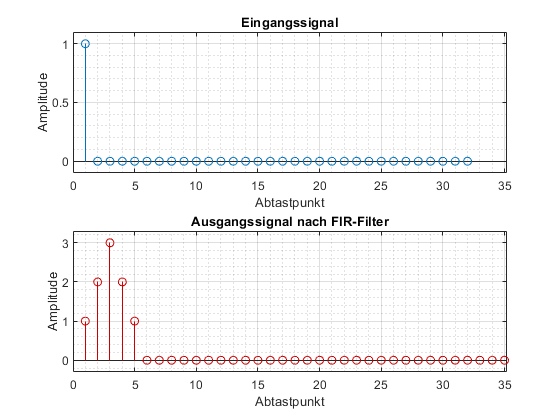

n_Symbols = 2^5;

%Dirac 
dirac_puls = zeros(1, n_Symbols);
dirac_puls(1) = 1;

coef = [1 2 3 2 1];                           %Vorwärstzweig
fir_system = FIR(dirac_puls, 4, coef);
%zum Probe ([1 0 0 0 0] = Rückwärtszweig)
%fir_system = filter(coef, [1 0 0 0 0], dirac_puls);        


figure (2)
subplot(2,1,1)
stem(dirac_puls)
stem_properties('Eingangssignal', 'Abtastpunkt', 'Amplitude', dirac_puls)
subplot(2,1,2)
stem(fir_system, 'Color',[0.8 0 0])
stem_properties('Ausgangssignal nach FIR-Filter', 'Abtastpunkt', 'Amplitude', fir_system)
xlim([0 length(dirac_puls)+length(dirac_puls)/10]); %zur Zentrierung mit Eingangssignal

#### **Testen für beliebige Eingangssignale mit Probe durch Faltung der Impulsantwort**

#### *1. Zufallstestsignal*

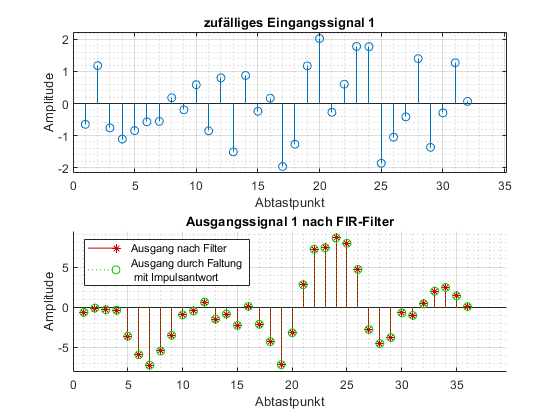

rng(1)
data3 = randn(1, n_Symbols);                %generieren des Zufallssignals

fir_system3 = FIR(data3, 4, coef);          %Ausgangssignalbestimmung durch Filterfunktion
fir_faltung3 = faltung(data3, coef);        %Ausgangssignalbestimmung durch Faltung mit Impulsantwort

figure (3)
subplot(2,1,1)
stem(data3)
stem_properties('zufälliges Eingangssignal 1', 'Abtastpunkt', 'Amplitude', data3)

subplot(2,1,2)
hold on
stem(fir_system3, 'Color',[0.8 0 0],'Marker',"*")
stem(fir_faltung3, 'Color',[0 0.8 0],'LineStyle',":")
stem_properties('Ausgangssignal 1 nach FIR-Filter', 'Abtastpunkt', 'Amplitude', fir_faltung3) 
hold off
legend('Ausgang nach Filter','Ausgang durch Faltung \newline mit Impulsantwort','Location','northwest')

#### *2. Zufallstestsignal*

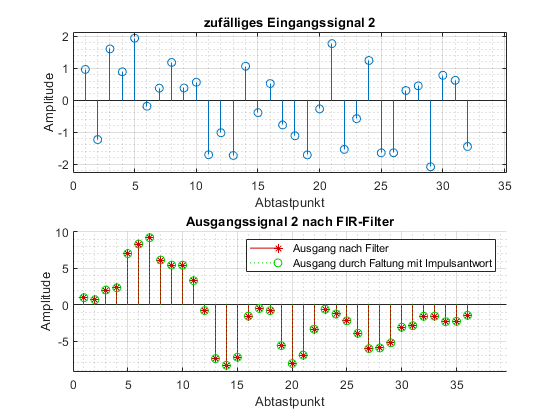

rng(13)                         
data4 = randn(1, n_Symbols);              

fir_system4 = FIR(data4, 4, coef);
fir_faltung4 = faltung(data4, coef);

figure (4)
subplot(2,1,1)
stem(data4)
stem_properties('zufälliges Eingangssignal 2', 'Abtastpunkt', 'Amplitude', data4)

subplot(2,1,2)
hold on
stem(fir_system4, 'Color',[0.8 0 0],'Marker',"*")
stem(fir_faltung4, 'Color',[0 0.8 0],'LineStyle',":")
stem_properties('Ausgangssignal 2 nach FIR-Filter', 'Abtastpunkt', 'Amplitude', fir_faltung4)
hold off
legend('Ausgang nach Filter','Ausgang durch Faltung mit Impulsantwort')

## IIR - Infinite Impulse Response

coef1 = [1 0 0 0 0];                        %Vorwärtszweig
coef2 = [0.9 0.81 0 0]; %coef2(0) = 1       %Rückkoppelzweig
iir_system = IIR(dirac_puls, 4, coef1, coef2);

figure (5)
subplot(2,1,1)
stem(dirac_puls)
stem_properties('Eingangssignal', 'Abtastpunkt', 'Amplitude', dirac_puls)
subplot(2,1,2)
stem(iir_system, 'Color',[0.8 0 0])
stem_properties('Ausgangssignal nach IIR-Filter', 'Abtastpunkt', 'Amplitude', fir_system)
xlim([0 length(dirac_puls)+(length(dirac_puls)/10)]); %zur Zentrierung mit Eingangssignal
ylim([-2 2])



% %Zur Probe:
% iir_system2 = filter(coef1, [0.9 0.81 0 0], dirac_puls);
% figure (4)
% subplot(2,1,1)
% stem(dirac_puls)
% stem_properties('Eingangssignal', 'Abtastpunkt', 'Amplitude', dirac_puls)
% subplot(2,1,2)
% stem(iir_system2, 'Color',[0.8 0 0])
% stem_properties('Ausgangssignal nach IIR-Filter', 'Abtastpunkt', 'Amplitude', fir_system)
% ylim([-2 2])


## Stabilitäts Probe der Übertragungsfunktion

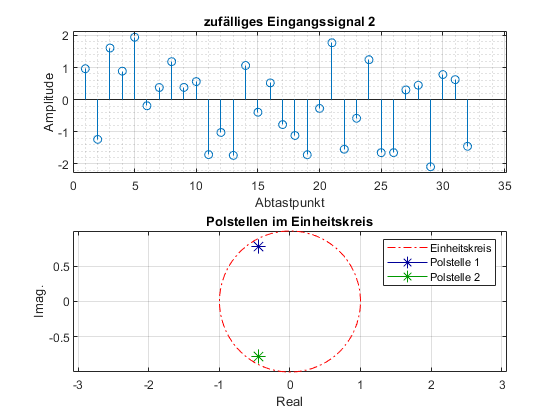

coef3 = [1 0.9 0.81];                       %gegebene Koeffizienten

Pol = roots(coef3);                         %suchen der Polstellen
Kreisumfang = linspace (0, 2*pi);           %Erstellung des Einheitskreises      
x = cos(Kreisumfang);
y = sin(Kreisumfang);

figure (4)
plot(x,y,'Color','r', "LineStyle",'-.');    %Einheitskreis
axis equal;                                 %mit symmetrischen Achsen
hold on
plot(real(Pol(1)),imag(Pol(1)),'Marker','*','Color',[0 0 0.6],"MarkerSize",10)         % Sobald die Beträge < 1 und damit im Einheitkreis sind
plot(real(Pol(2)),imag(Pol(2)),'Marker','*','Color',[0 0.6 0],"MarkerSize",10)         % --> System ist stabil
xlabel('Real')
ylabel('Imag.')
grid on;
hold off;
title ('Polstellen im Einheitskreis')
legend ('Einheitskreis','Polstelle 1','Polstelle 2')        

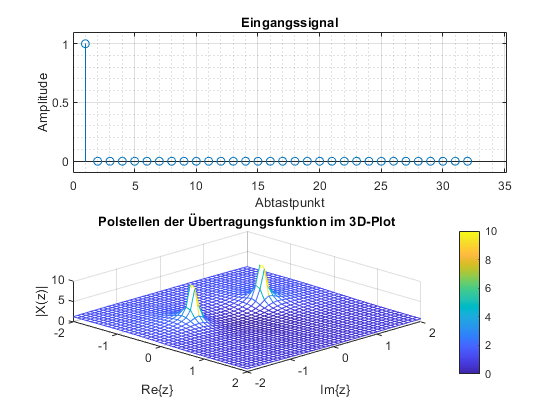



% Darstellung im 3D-Plot (meshgrid)

[x_Real,y_Imag] = meshgrid (-2:0.1:2);   %quadratisches "Meshgrid" (Grenzen von -2 bis 2 in 0,1 Schritten) --> spannt die komplexe Ebene auf
z = x_Real + 1j * y_Imag;                %z soll auf der komplexen Ebene dargestellt werden
x = z.^2 ./ (z.^2 + 0.9*z + 0.81);       %Übertragungsfunktion (Herleitung im Protokoll)
%surf(x,y,x)

figure (5);
mesh (x_Real, y_Imag, abs(x))
view([45 60])
xlim ([-2 2])
ylim ([-2 2])
zlim ([0 10]); 
caxis ([0,10]);                          %caxis = Limit für die Colormap
xlabel ('Re\{z\}')                       %(Achsenbeschriftung wie in Vorlesung)
ylabel ('Im\{z\}')
zlabel ('|X(z)|')
title  ('Polstellen der Übertragungsfunktion im 3D-Plot')
colorbar

## Lineare, zeitinvariante Systeme bei Erregung

#### z_inf = 1.1


k = -50:1:100;
z = 1.1

z = 1.1000


x= z.^k;
%Koeffizientenvektor Eingangsignal (b)
b = 1 

b = 1

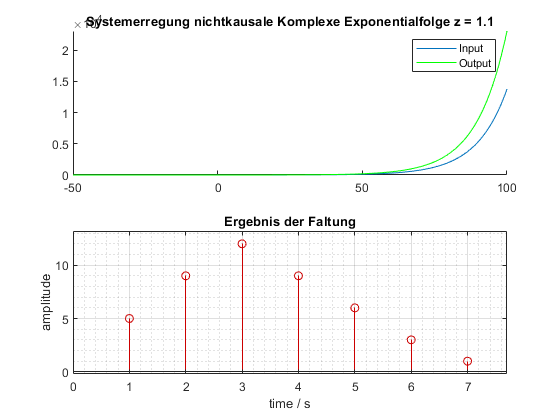

%Koeffizientenvektor am Augang Rückgekoppelt (c)
c = [1 0.9 0.81];
y = IIR(x,4,b,c);

figure (1)
subplot (2,1,1)
hold on
plot (k,x)
plot (k,y,'g')
legend ('Input', 'Output')
title ('Systemerregung nichtkausale Komplexe Exponentialfolge z = 1.1')

q = y ./ x;
subplot (2,1,2)

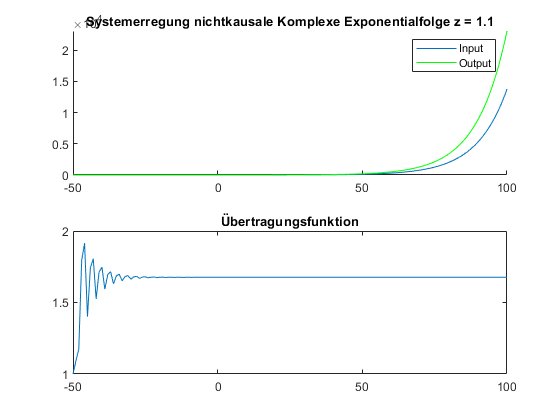

plot (k,q)
title ('Übertragungsfunktion')

#### z_inf = 1.1*e^(j*(pi/7)

z= 1.1 * exp(1j*pi/7);
x= z.^k;
y = IIR(x,4,b,c);

figure (2)
subplot (2,1,1)
hold on;
plot (k,x)

plot (k,y,'r')

legend ('Input', 'Output')
title ('Systemerregung nichtkausale Komplexe Exponentialfolge z = 1.1e^(j*Pi)/7')

q = y ./ x;
subplot (2,1,2)
plot (k,q)

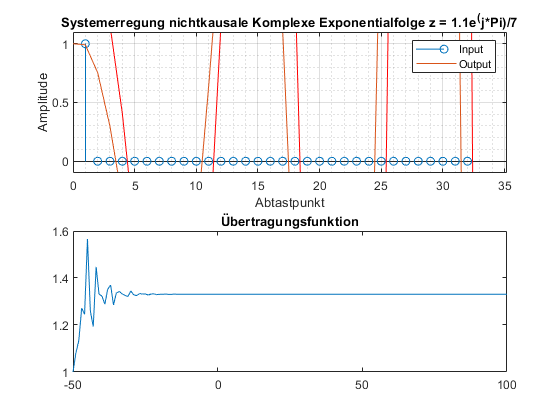

title ('Übertragungsfunktion')

#### z_inf = 1.1*e^(j*(6pi/5)


z= 1.2 * exp(1j*6*pi/5);
x= z.^k;
y = IIR(x,4,b,c);

figure (3)
subplot (2,1,1)
hold on;
plot (k,x)

plot (k,y)

legend ('Input', 'Output')
title ('Systemerregung nichtkausale Komplexe Exponentialfolge z = 1.2 * exp(1j*6*pi/5);')

q = y ./ x;
subplot (2,1,2)
plot (k,q)

title ('Übertragungsfunktion')
plot (k,q)

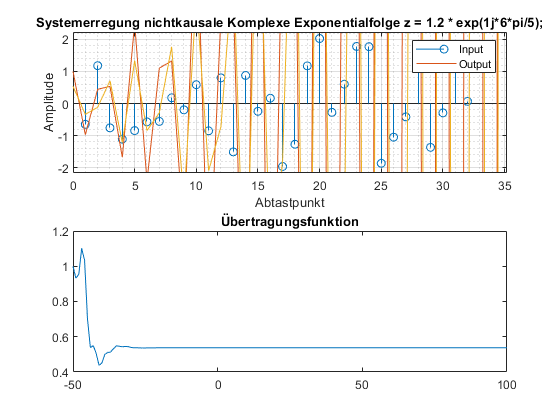

title ('Übertragungsfunktion')